# Tema 9

**Pb 1.** Sa se gaseasca aproximanta discreta prin metoda celor mai mici patrate pentru ponderea w(x)=1 si baza 1; x; x^2; ... ; x^n.

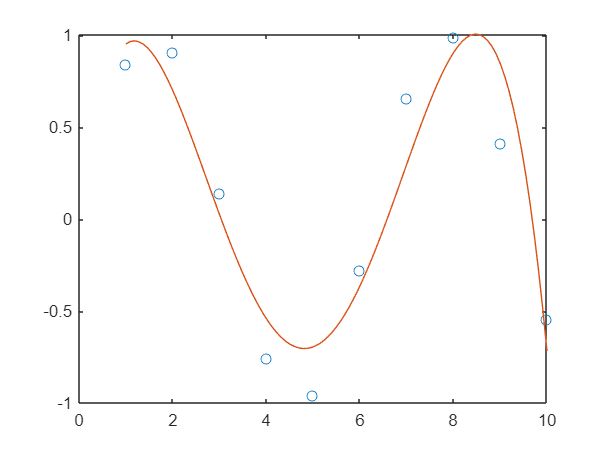

x = 1 : 10;
y = sin(1 : 10);

baza = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4];

x_approx = x(1) : (x(length(x)) - x(1)) / 100 : x(length(x));
y_approx = lsq_approx(x, y, baza, x_approx);

plot(x, y, 'o', x_approx, y_approx, '-');

**Pb 3.** La masurarea unui segment de drum, presupunem ca am efectuat 5 masuratori AD = 89m; AC = 67m; BD = 53m; AB = 35m si CD = 20m. Sa se determine lungimile segmentelor x1 = AB, x2 = BC si x3 = CD.

% x1 +  x2 + x3 = 89
% x1 + x2 = 67
% x2 + x3 = 53
% x1 = 35
% x3 = 20
A = [1 1 1; 1 1 0; 0 1 1; 1 0 0; 0 0 1];
b = [89; 67; 53; 35; 20];
(A\b)'

ans =    35.1250   32.5000   20.6250


**Pb 4.** 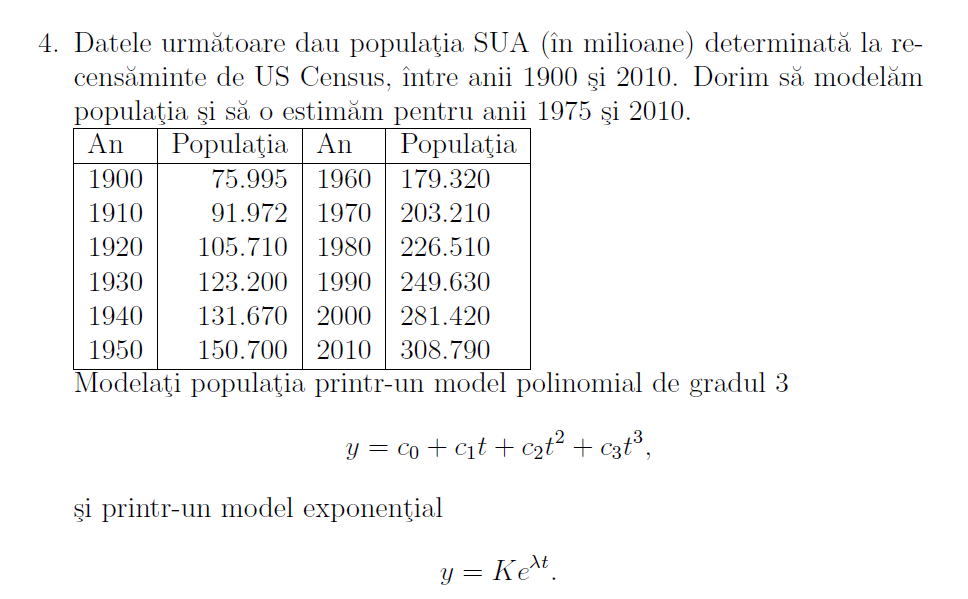

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995  91.972 105.710 123.200 131.670 150.700 179.320 203.210 226.510 249.630 281.420 308.790];

t = 1890:1:2019;
xx = [1965 2015];

% polinom de grad 3
coefs = polyfit(x, y, 3)

coefs = 	1.0e+04 *

   -0.0000    0.0000   -0.0109    7.9954


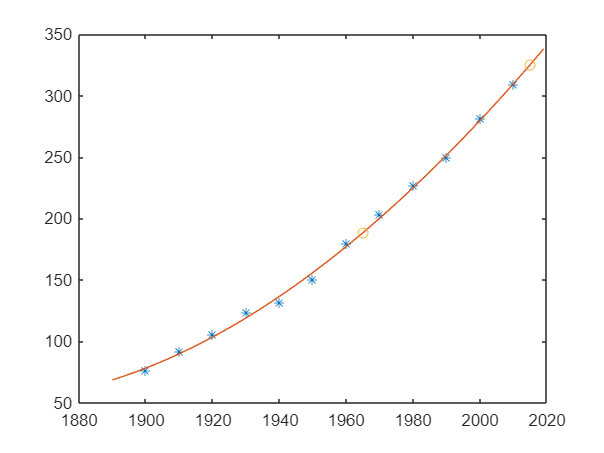

plot(x, y, '*');
hold on;
plot(t, polyval(coefs, t), '-');
plot(xx, polyval(coefs, xx), 'o');
hold off;


% model exponential
coefs2 = polyfit(x, log(y), 1)

coefs2 =     0.0126  -19.5372


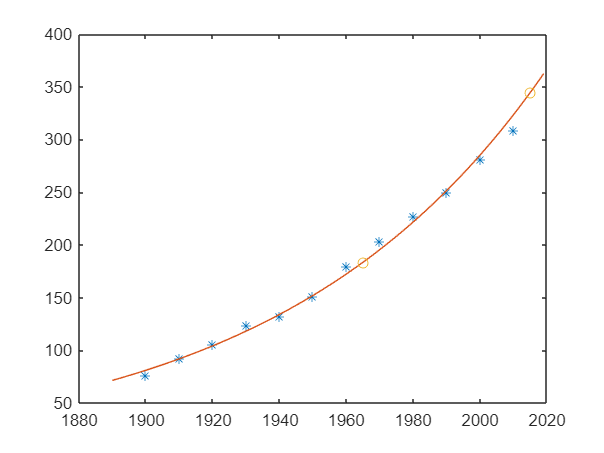

K = exp(coefs2(2));
lambda = coefs2(1);
f = @(t) K * exp(lambda * t);

plot(x, y, '*');
hold on;
plot(t, f(t), '-');
plot(xx, f(xx), 'o');
hold off;